# Si-CLASH Master Synchronizer Live Explorer (Pure Cycle-Accurate Fixed-Point)

Runs the complete end-to-end Transmitter, Physical Channel / ADC Front-End, and Blind Three-Stage Cycle-Accurate Fixed-Point Receiver Synchronization pipeline.

clear; clc; close all;
cur_file = mfilename('fullpath');
if ~isempty(cur_file)
    search_dir = fileparts(cur_file);
else
    search_dir = pwd;
end
for depth = 1:4
    if exist(fullfile(search_dir, 'setup_project.m'), 'file')
        addpath(search_dir);
        break;
    end
    search_dir = fileparts(search_dir);
end
setup_project(false);

[SETUP] Synchronizer paths added and .mlx Live Scripts compiled in live_scripts/.


## 1. Configure Full-Burst Simulation (QPSK or 16-QAM)

cfg = get_hw_config();
cfg.mod_type        = 0;             % 0 = QPSK, 1 = 16-QAM
cfg.snr_dB          = 18.0;          % Requested SNR (dB)
cfg.tau_offset      = 0.35;          % Fractional timing skew in Ts
cfg.cfo_norm        = 0.065;         % +6.5% Rsym Carrier Frequency Offset
cfg.phase_offset    = 115*(pi/180);  % Arbitrary initial carrier phase (tests quadrant recovery)

## 2. Generate Burst Frame, RRC Pulse Shaping & Channel / ADC Front-End (/2 & Q1.11 Clip)

[rx_samples, tx_payload, frame_info] = generate_frame(cfg);
in_valid = true(size(rx_samples));

## 3. Run Cycle-Accurate Fixed-Point Synchronizer & Print Specification Report

rx_out  = run_cycle_accurate_top(rx_samples, in_valid, cfg);
metrics = compute_evm_and_metrics(rx_out, tx_payload, cfg);

fprintf('------------------------------------------------------------\n');

------------------------------------------------------------


fprintf('  SYNCHRONIZER PERFORMANCE REPORT\n');

  SYNCHRONIZER PERFORMANCE REPORT


fprintf('------------------------------------------------------------\n');

------------------------------------------------------------


fprintf('  PRIMARY METRIC - Excess EVM : %8.4f %%\n', double(metrics.evm_excess_pct));

  PRIMARY METRIC - Excess EVM :   2.8711 %


fprintf('  Total EVM (RMS)             : %8.4f %%\n', double(metrics.evm_total_pct));

  Total EVM (RMS)             :   6.9180 %


fprintf('  Floor EVM (Es/N0=%.2fdB)   : %8.4f %%\n', metrics.esn0_dB, double(metrics.evm_floor_pct));

  Floor EVM (Es/N0=24.02dB)   :   6.2930 %


fprintf('  Symbol Error Rate (SER)     : %8.4f\n', double(metrics.ser));

  Symbol Error Rate (SER)     :   0.0000


fprintf('  STR Timing Jitter (RMS)     : %8.4f Ts (Target: <= 0.0200)\n', metrics.timing_jitter_Ts);

  STR Timing Jitter (RMS)     :   0.0155 Ts (Target: <= 0.0200)


fprintf('  STR Lock Symbol             : %8.0f\n', double(metrics.str_lock_sym));

  STR Lock Symbol             :       54


fprintf('  Coarse CFO Done Symbol      : %8.0f\n', double(rx_out.coarse_done_sym));

  Coarse CFO Done Symbol      :       90


fprintf('  Costas Public Lock Symbol   : %8.0f\n', double(metrics.costas_lock_sym));

  Costas Public Lock Symbol   :      189


fprintf('  Quadrant Ambiguity k        : %8.0f (unres=%d)\n', double(rx_out.quad_k), rx_out.quad_unresolved);

  Quadrant Ambiguity k        :        1 (unres=0)


fprintf('  Coarse CFO Estimate (turns) : %+8.5f (True: %+8.5f)\n', double(rx_out.coarse_cfo_est), cfg.cfo_norm);

  Coarse CFO Estimate (turns) : +0.06490 (True: +0.06500)


fprintf('  Fine CFO Estimate (turns)   : %+8.5f (Error: %8.5f)\n', double(rx_out.fine_cfo_est), metrics.fine_cfo_err);

  Fine CFO Estimate (turns)   : +0.06508 (Error:  0.00008)


fprintf('  Evaluated Payload Symbols   : %8d\n', metrics.n_eval);

  Evaluated Payload Symbols   :     1200


fprintf('------------------------------------------------------------\n');

------------------------------------------------------------


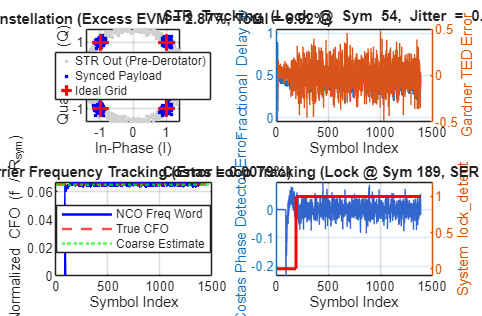


plot_sync_diagnostics(rx_out, metrics, cfg);